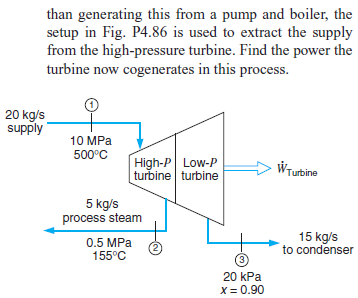

# symbolic units class

u = symunit;

# state 1 (superheated steam)

% ----------------
% given
mdot1 = 20*u.kg/u.s;
p1 = 10*u.MPa;
T1 = 500*u.Celsius;
% ----------------
% specific enthalpy
h1 = 3373.63*u.kJ/u.kg;
% ----------------

# state 2 (saturated vapor water)

% ----------------
% given
mdot2 = 5*u.kg/u.s;
p2 = 0.5*u.MPa;
T2 = 155*u.Celsius;
% ----------------
% specific enthalpy
h2 = interp1([151.86 200], [2748.67 2855.37], 155)*u.kJ/u.kg;
% ----------------

# state 3 (liquid-vapor water mix)

% ----------------
% given
mdot3 = sym('mdot3');
p3 = 20*u.kPa;
T3 = 60.06*u.Celsius;
x3 = 0.90;
% ----------------
% specific enthalpy
hf3 = 251.38*u.kJ/u.kg;
hfg3 = 2358.33*u.kJ/u.kg;
h3 = hf3+x3*hfg3;
% ----------------

# conservation of mass

mdot3 = solve(mdot1 == mdot2+mdot3);
mdot3_vpa = vpa(mdot3) %#ok

$$mdot3\_vpa = 15.0\,\frac{\mathrm{kg}}{s}$$

clear mdot3_vpa;

# conservation of energy

Wdot = sym('Wdot');
Wdot = rewrite(solve(mdot1*h1 == mdot2*h2+mdot3*h3+Wdot), u.MW);
Wdot_vpa = vpa(Wdot) %#ok

$$Wdot\_vpa = 18.086296703365190114709548652172\,\mathrm{MW}$$

clear Wdot_vpa;